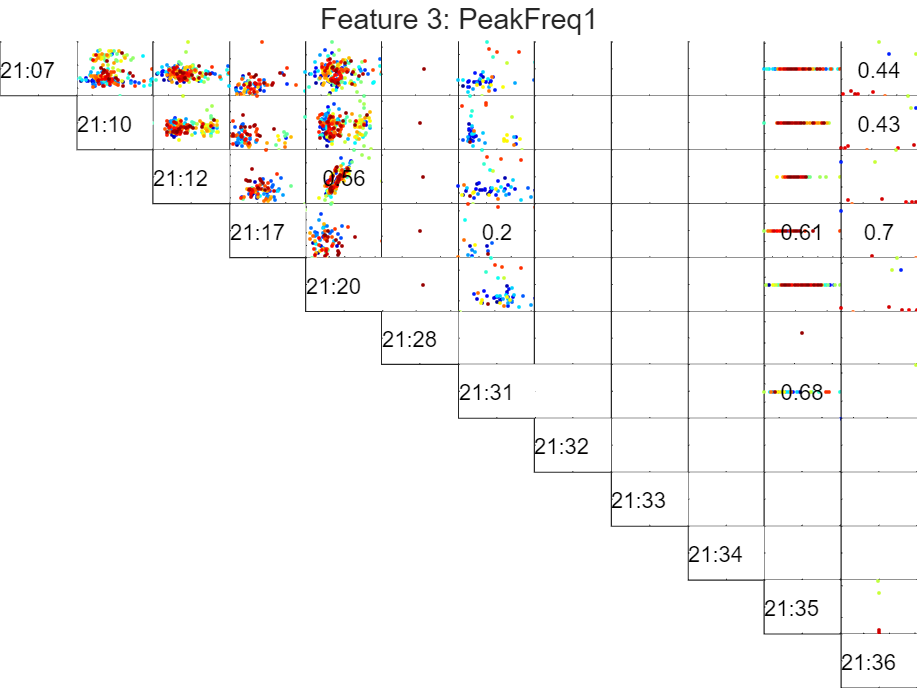

Features = DFD_FeatureTable_FreqDomain;
FeatureNames = featureNames_Freq;
SignalNames = signalNames_Freq;
lowerR2 = 0.2;
upperR2 = 0.8;
featureNum = 3;
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, featureNum, FeatureNames, SignalNames, sensorNames);

disp(num2str(R2, '%.2f  '));

0.00   0.00   0.00   0.11   0.00    NaN   0.14    NaN    NaN    NaN   0.81   0.44
0.00   0.00   0.01   0.01   0.01    NaN   0.05    NaN    NaN    NaN   0.85   0.43
0.00   0.00   0.00   0.00   0.56    NaN   0.01    NaN    NaN    NaN   0.82   0.04
0.00   0.00   0.00   0.00   0.00    NaN   0.20    NaN    NaN    NaN   0.61   0.70
0.00   0.00   0.00   0.00   0.00    NaN   0.00    NaN    NaN    NaN   0.82   0.05
0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN    NaN    NaN    NaN    NaN
0.00   0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN    NaN   0.68   1.00
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN    NaN    NaN
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN    NaN
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00  -0.00
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00


selectedSignal = 3; % row 1
selectedSignalArray = [selectedSignal]; % Array of correlated features
for i = 1:numOfSignals + 1 - selectedSignal
    if R2(i,selectedSignal) > lowerR2 && R2(i,selectedSignal) < upperR2
        selectedSignalArray = [selectedSignalArray i];
    end
end
for i = selectedSignal + 1:numOfSignals
    if R2(selectedSignal,i) > lowerR2 && R2(selectedSignal,i) < upperR2
        selectedSignalArray = [selectedSignalArray i];
    end
end
selectedSignalArray = sort(selectedSignalArray);
numOfSelectedSignals = size(selectedSignalArray, 2);
selectedSignalData = {numOfSelectedSignals};

for signalIndex = 1:numOfSelectedSignals
    selectedSignalData{signalIndex} = Features.(SignalNames(selectedSignalArray(signalIndex)) + FeatureNames(featureNum));
end
disp(selectedSignalArray);

     3     5



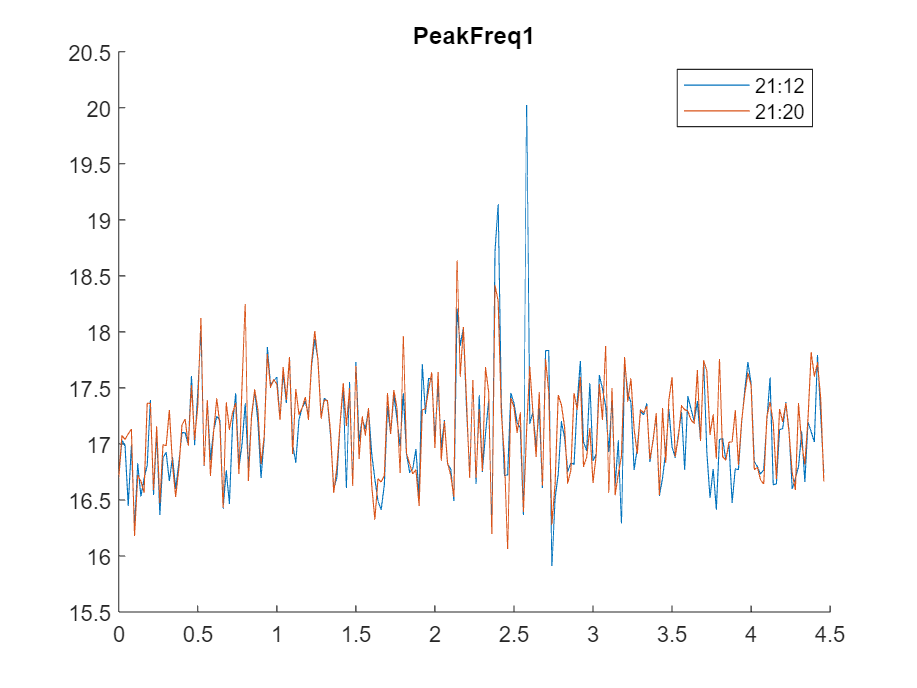

n = size(selectedSignalData{1}, 1);
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
leg = {numOfSelectedSignals};
for i = 1:numOfSelectedSignals
    plot(t, selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
title(FeatureNames(featureNum));
legend(leg);

X_signals = zeros(n, numOfSelectedSignals);
for i = 1:numOfSelectedSignals
    X_signals(:,i) = selectedSignalData{i}; 
end

X_1 = X_signals(:,1);
X_2 = X_signals(:,2);
%X_3 = X_signals(:,3);

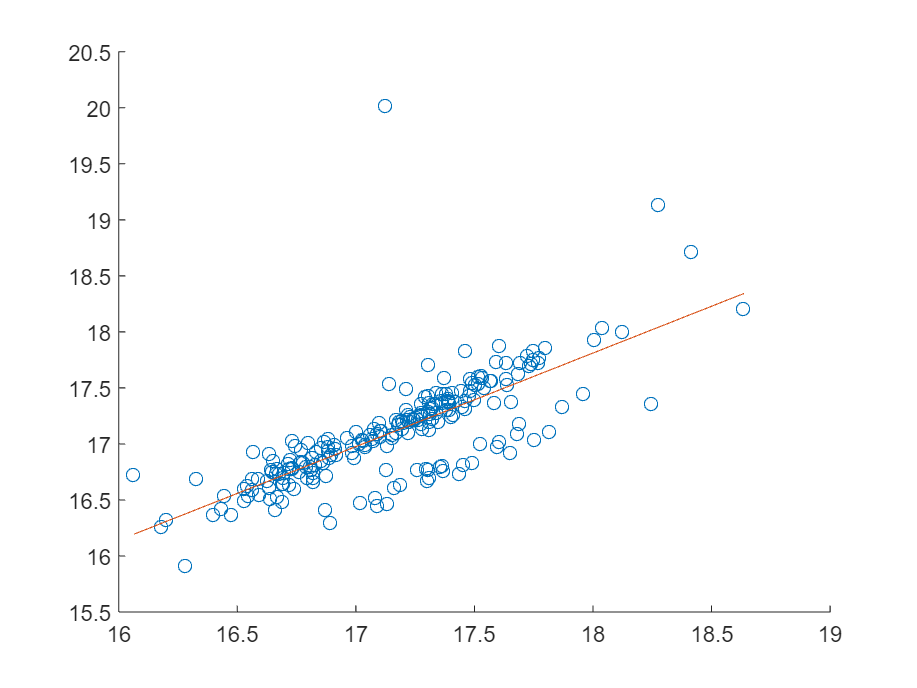

% Single variable Model candidate 1: Y = X1, X = X2
X1 = X_2;
X = [ones(n,1) X1];
Y = X_1;
k = size(X, 2) - 1; % Number of parameters for model
beta = inv(X' * X) * (X' * Y);

Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

figure(); hold on;
scatter(X1, Y);
interval = max(X1) - min(X1);
x1fit = min(X1):interval:max(X1);
yfit = beta(1) + beta(2).*x1fit;
plot(x1fit, yfit);